% Análisis de Phase Matching
% Proyecto 2. Fotónica & Tecnologías Cuánticas
% Daniel Santiago Rueda, Isabella Ruiz.

%Ruta_Neff = 'NeffTE/N_eff_Alt2Anc5.txt'; % Caso asimétrico
Ruta_Neff = 'NeffTE/N_eff_Alt2Anc4.txt'; % Caso simétrico

Neff_txt = fopen(Ruta_Neff, 'r');

% Creación del array de indice efectivo
Neff = [];
i = 1;
while ~feof(Neff_txt)
    linea = fgetl(Neff_txt);
    if ischar(linea)
        numero = str2double(linea);
        if (numero ~= 0.) % Limpieza, no se incluyen los '0's
            Neff(end+1) = numero;
            i = i+1;
        end
    end
end

lambda = linspace(0.5, 1.6, 15);
lambda = lambda(1,1:length(Neff)); % Se trunca el numero de puntos de longitud de onda

function coefficients = coeff_fit(x, y)
    [model, gof] = fit(x', y', 'poly4'); % Modelo cuártico
    coefficients = [model.p5, model.p4, model.p3, model.p2, model.p1];
end

coeff_TE = coeff_fit(lambda, Neff);

% figure;
% hold on;
% plot(lambda, coeff_TE(1) + coeff_TE(2)*lambda + coeff_TE(3)*lambda.^2 + coeff_TE(4)*lambda.^3 + coeff_TE(5)*lambda.^4);
% scatter(lambda, Neff, 'filled');
% xlabel('$\lambda (\mu m)$', 'Interpreter','latex');
% ylabel('$N_{eff}$', 'Interpreter','latex');
% legend({'Ajuste', 'Datos'},'Interpreter','latex')
% hold off;

lamp = linspace(0.5, 1.6, 200); % Longitud de onda pump 0.5 1.6
lams = linspace(0.5, 1.6, 200); % Longitud de onda signal 0.5 1.6
lami = 1./(2./lamp - 1./lams);

[LAMP, LAMS] = meshgrid(lamp, lams);
LAMI = 1./(2./LAMP - 1./LAMS); % Longitud de onda idler -> Conservacion del momento

function neff_lambda = neff_lambda(lambdas, coeff)
    neff_lambda = coeff(1) + coeff(2).*lambdas + coeff(3).*lambdas.^2 + coeff(4).*lambdas.^3 + coeff(5).*lambdas.^4;
end

function klambda = k_lambda(lambdas, coeff)
    neff = coeff(1) + coeff(2).*lambdas + coeff(3).*lambdas.^2 + coeff(4).*lambdas.^3 + coeff(5).*lambdas.^4;
    klambda = ((2*pi)./lambdas).*neff;
end

function dkdw = dkdw(lambdas, coeff)
    neff = coeff(1) + coeff(2).*lambdas + coeff(3).*lambdas.^2 + coeff(4).*lambdas.^3 + coeff(5).*lambdas.^4;
    dneff = coeff(2) + 2*coeff(3).*lambdas + 3*coeff(4).*lambdas.^2 + 4*coeff(5).*lambdas.^3;
    dkdw = 1/(3e14)*(neff - lambdas.*dneff);
end

% function ddkdw = ddkdw(dkdw)
%     ddkdw = gradient(dkdw);
% end

% function disp = dispersion(lambdas, coeff)
%         ddneff = 2*coeff(3) + 6*coeff(4).*lambdas + 12*coeff(5).*lambdas.^2;
%         disp = -(1/3e14).*lambdas.*ddneff;
% end

L = 20000; % 2 cm de longitud 

kp = k_lambda(LAMP, coeff_TE);
ks = k_lambda(LAMS, coeff_TE);
ki = k_lambda(LAMI, coeff_TE);

Deltak = kp + kp - ks - ki - 1e-6;
dkdwp = dkdw(LAMP, coeff_TE);
dkdws = dkdw(LAMS, coeff_TE);
dkdwi = dkdw(LAMI, coeff_TE);

tau_s = L*(dkdwp - dkdws);
tau_i = L*(dkdwp - dkdwi);

%%% Contornos de phase matching %%%%

% figure;
% hold on;
% contour(LAMP, LAMS, Deltak, [0, 0], 'k')
% contour(LAMP, LAMS, tau_s, [0, 0], 'r')
% contour(LAMP, LAMS, tau_i, [0, 0], 'g')
% xlabel('$\lambda_p (\mu m)$', 'Interpreter','latex')
% ylabel('$\lambda_s, \lambda_i (\mu m)$', 'Interpreter','latex')
% contour(LAMP, LAMS, tau_s+tau_i, [0, 0], 'b')
% legend({'$\Delta k = 0$', '$\tau_i = 0$'},'Interpreter','latex')
% axis square;
% grid on;
% hold off;

%%%% JSA %%%%

format long;

% Longitudes de onda phase matching

%Caso asimetrico
% lambda_phm_p = 0.863968;
% lambda_phm_s = 0.600623;
% lambda_phm_i = 1.538571;

%Caso simétrico
lambda_phm_p = 0.821920;
lambda_phm_s = 0.560090;
lambda_phm_i = 1.543458;

k_phm_p = k_lambda(lambda_phm_p, coeff_TE);
k_phm_s = k_lambda(lambda_phm_s, coeff_TE);
k_phm_i = k_lambda(lambda_phm_i, coeff_TE);

omega_phm_s = (3e14.*k_phm_s)./neff_lambda(lambda_phm_s, coeff_TE);
omega_phm_i = (3e14.*k_phm_i)./neff_lambda(lambda_phm_i, coeff_TE);
omega_phm_p = (3e14.*k_phm_p)./neff_lambda(lambda_phm_p, coeff_TE);

delta = 0.001e15; % Tamaño del intervalo de graficación en el espacio {ws, wi}

dk0 = 2*k_phm_p - k_phm_s - k_phm_i;

omega_s = linspace(omega_phm_s - delta, delta + omega_phm_s, 200);
omega_i = linspace(omega_phm_i - delta, delta + omega_phm_i, 200);

[WS, WI] = meshgrid(omega_s, omega_i);

nu_s = WS - omega_phm_s; % nu_mu = w_mu - w_0mu
nu_i = WI - omega_phm_i;

dkdwp_phm = dkdw(lambda_phm_p, coeff_TE);
dkdws_phm = dkdw(lambda_phm_s, coeff_TE);
dkdwi_phm = dkdw(lambda_phm_i, coeff_TE);

tau_s_phm = L*(dkdwp_phm - dkdws_phm);
tau_i_phm = L*(dkdwp_phm - dkdwi_phm);

sigma = sqrt(2./(0.193.*abs(tau_s_phm*tau_i_phm))) % Condición sobre anchos de banda

sigma =      1.623909594799076e+12


delta_lambda_laser = 3e14/(3e14/lambda_phm_p - sigma/2) - 3e14/(3e14/lambda_phm_p + sigma/2) % Ancho de banda en lambda

delta_lambda_laser =    0.003656805310832


%%%% Approximate Form JSA %%%%

function alpha = alpha(nu_s, nu_i, sigma)
    alpha = exp(-(nu_s+nu_i).^2./(2*sigma^2));
end

function phi = phi(nu_s_, nu_i_, tau_s, tau_i)
    % Aquí se asume phase matching perfecto
    dk =  tau_s.*nu_s_ + tau_i.*nu_i_;
    phi = (2./dk).*sin(0.5*dk).*exp(0.5j*dk);
end

alpha_phm = alpha(nu_s, nu_i, sigma);
phi_phm = phi(nu_s, nu_i, tau_s_phm, tau_i_phm);

JSA_Approx = phi_phm.*alpha_phm;

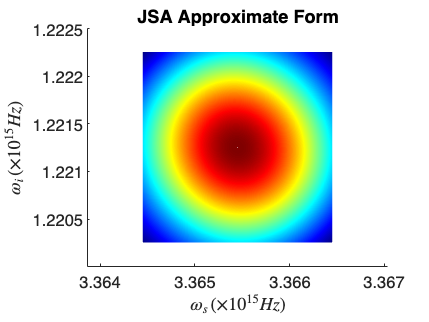

figure;
surf(WS*1e-15, WI*1e-15, abs(JSA_Approx).^2), shading interp;
view(2);
colormap jet;
grid off;
axis equal;
title('JSA Approximate Form')
xlabel('$\omega_s \,(\times 10^{15} Hz)$', 'Interpreter','latex')
ylabel('$\omega_i \,(\times 10^{15} Hz)$', 'Interpreter','latex')

%%%% Integral Form JSA %%%%

function k_omega = k_omega(omega, lambda, coeff_TE)
    neff = neff_lambda(lambda, coeff_TE);
    k_omega = omega.*neff./3e14;
end

alpha_int = @(w) (1/sqrt(sigma * sqrt(pi))) * exp(-((w - omega_phm_p).^2) / (2 * sigma^2));

JSA_Int = zeros(numel(omega_s), numel(omega_i));

for i = 1:numel(omega_s)
    for j = 1:numel(omega_i)
        dkk = @(w) k_omega(w, 2*pi*3e14./w, coeff_TE) + k_omega(omega_s(i) + omega_i(j) - w, 2*pi*3e14./(omega_s(i) + omega_i(j) - w), coeff_TE) - k_omega(omega_i(j), 2*pi*3e14./omega_i(j), coeff_TE) - k_omega(omega_s(i), 2*pi*3e14./omega_s(i), coeff_TE);
        integrand = @(w) alpha_int(w).*alpha_int(omega_s(i) + omega_i(j) - w).*sin(L.*dkk(w)./2).*exp(1j.*L.*dkk(w)./2)./(0.5.*L.*dkk(w));
        JSA_Int(j, i) = integral(integrand, omega_phm_p - 0.005*delta, omega_phm_p + 0.005*delta);
    end
end


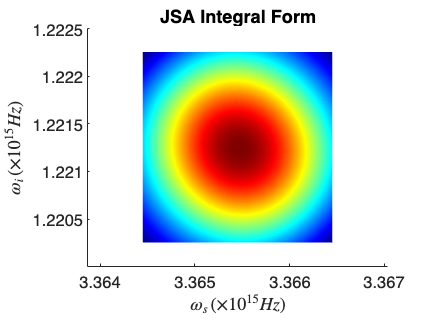

figure;
surf(WS*1e-15, WI*1e-15, abs(JSA_Int).^2), shading interp;
view(2);
colormap jet;
grid off;
axis equal;
title('JSA Integral Form')
xlabel('$\omega_s \,(\times 10^{15} Hz)$', 'Interpreter','latex')
ylabel('$\omega_i \,(\times 10^{15} Hz)$', 'Interpreter','latex')

%%%% Schmidt Decomposition %%%%

[U, S, V] = svd(JSA_Int); % Singular Value Decomposition

singular_values = diag(S);
Normalization = sum(singular_values);

Schmidt_coeff = singular_values/Normalization; % sum(lambda_j) = 1

K = 1/sum(Schmidt_coeff.^2);

P = 1/K % Pureza

P =    0.977817656789300


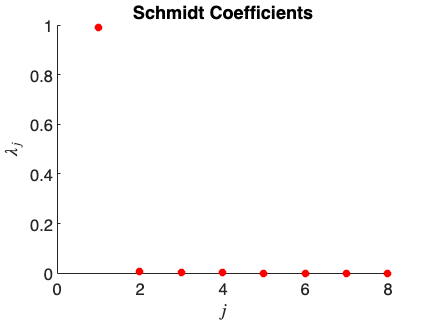

% Coeficientes de Schmidt
scatter((1:8), Schmidt_coeff(1:8), 20, 'filled', 'red');
grid off;
title('Schmidt Coefficients')
xlabel('$j$', 'Interpreter','latex')
ylabel('$\lambda_j$', 'Interpreter','latex')